% 温度补偿代码，预计采用两种形式：两点补偿，多项式拟合。


% 读取热盘和晶元传感器原始温度数据。
heater_rawdata = readtable("TempCalibration\temp150_1.txt");
wafer_raw_data = readtable("TempCalibration\20240822_110655_DatCHLOG_temp150_1.csv","VariableNamingRule","preserve");

% 过滤数据，只保留有效的温度值，并另两部分的数据高度一致
wafer_filtered_data = table2array(wafer_raw_data(:,3:end));
waferdataheight = height(wafer_filtered_data);
heater_filtered_data = table2array(heater_rawdata(end-waferdataheight+1:end,1:7));

% 将晶元传感器的多点温度值平均后对应至热盘传感器温度
% 对应规则如下：
% P1 - CH1、2、3、4、5、6、7、8、9
% P2 - CH2、3、4、8、9
% P3 - CH4、5、6、7、8
% P4 - CH19、20、21、33、34
% P5 - CH21、22、23、24、25
% P6 - CH25、26、27、28、29
% P7 - CH29、30、31、32、33
wafer_average_to_heater = zeros(waferdataheight,7);
wafer_average_to_heater(:,1) = sum(wafer_filtered_data(:,1:9),2)./9;
wafer_average_to_heater(:,2) = sum(wafer_filtered_data(:,[2 3 4 8 9]),2)./5;
wafer_average_to_heater(:,3) = sum(wafer_filtered_data(:,4:8),2)./5;
wafer_average_to_heater(:,4) = sum(wafer_filtered_data(:,[19 20 21 33 34]),2)./5;
wafer_average_to_heater(:,5) = sum(wafer_filtered_data(:,21:25),2)./5;
wafer_average_to_heater(:,6) = sum(wafer_filtered_data(:,25:29),2)./5;
wafer_average_to_heater(:,7) = sum(wafer_filtered_data(:,29:33),2)./5;


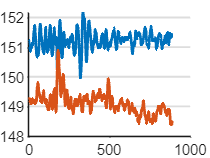

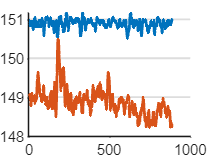

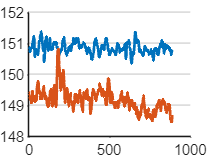

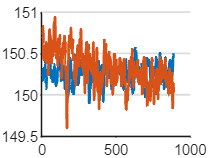

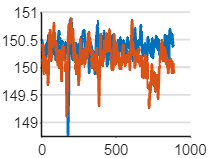

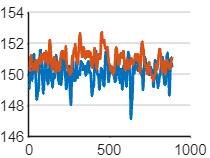

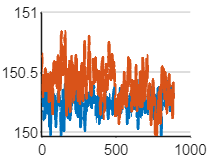

% 画出二者对应点的折线图
X = linspace(1,888,888);
for i = 1:1:7
    figure;
    plot(X, heater_filtered_data(:,i), ...
         "DisplayName", sprintf("Heater %d",i), ...
         "LineWidth", 1.5);
    hold on;
    plot(X, wafer_average_to_heater(:,i), ...
        "DisplayName", sprintf("Wafer average %d",i), ...
        "LineWidth", 1.5);
    set(gca,'Box','off', ...                                % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                     % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    hold off;
end

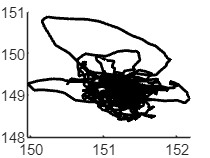

错误使用 plot
'.' 是无效值。请使用以下某个值: '-' | '--' | ':' | '-.' | 'none'。

% 真假值散点图
for i = 1:1:7
    figure;
    plot(heater_filtered_data(:,i), wafer_average_to_heater(:,i), ...
         "DisplayName", sprintf("Heater %d",i), ...
         "LineWidth", 1.5, ...
         "LineStyle",".");
    hold on;
    set(gca,'Box','off', ...                                % 边框开关
        'LineWidth',1, ...                                  % 线宽（非数据线）
        'XGrid','off','YGrid','on', ...                     % 网格开关
        'TickDir','out','TickLength',[0.01 0.01], ...       % 刻度调整，朝外、0.01
        'XMinorTick', 'off', 'YMinorTick', 'off', ...       % 小刻度开关
        'XColor', [.1 .1 .1],  'YColor', [.1 .1 .1]);       % 坐标轴颜色
    hold off;
end